# Rad229_OffRes_Dist_Demo.mlx demonstrates off-resonance distortion echo planar imaging (EPI).

DBE@STANFORD.EDU (May 2020) for Rad229

## Default parameters

%% Define MRI system and acquisition constants
sys = Rad229_MRI_sys_config;

acq.Nx = 128;                 % Matrix is NxN
acp.ESP = 500e-6;             % Echo spacing [s]

## Generate the phantom object

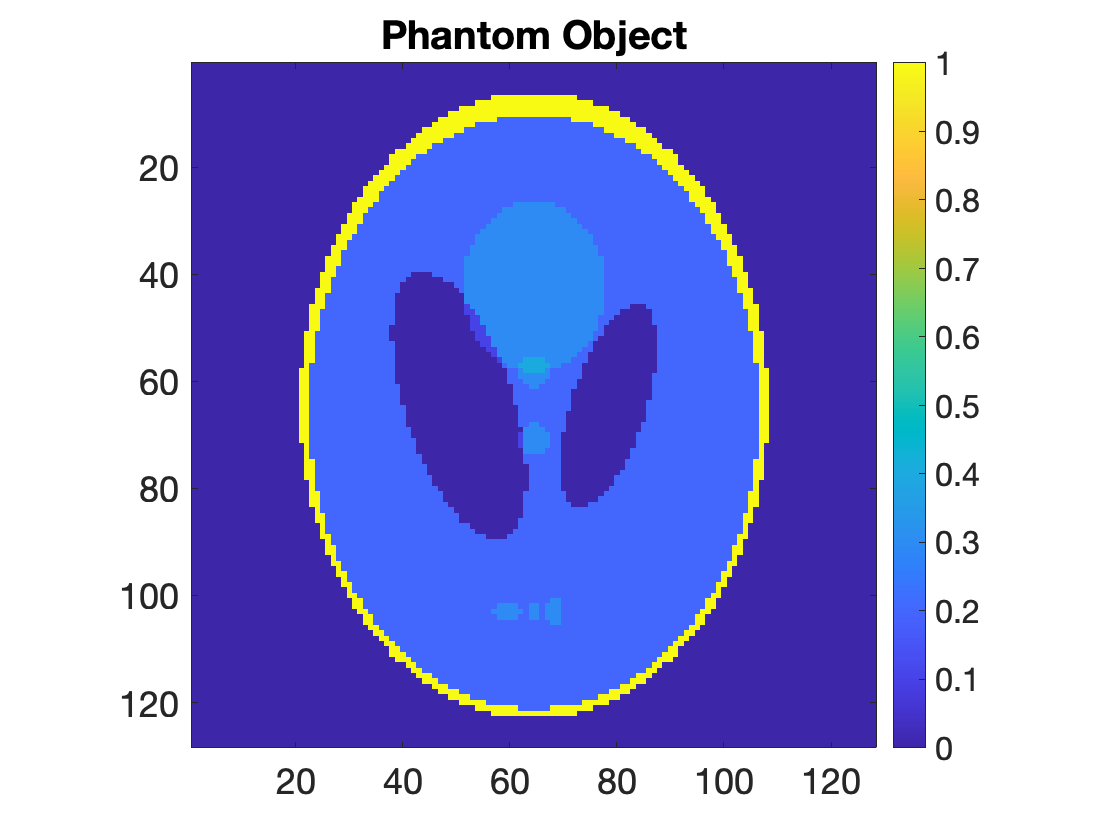

[ P , M ] = Rad229_MRI_Phantom( acq );

figure; imagesc(P); axis equal tight; title('Phantom Object'); 
  colorbar; caxis([0 1]);

## Create an off-resonance field

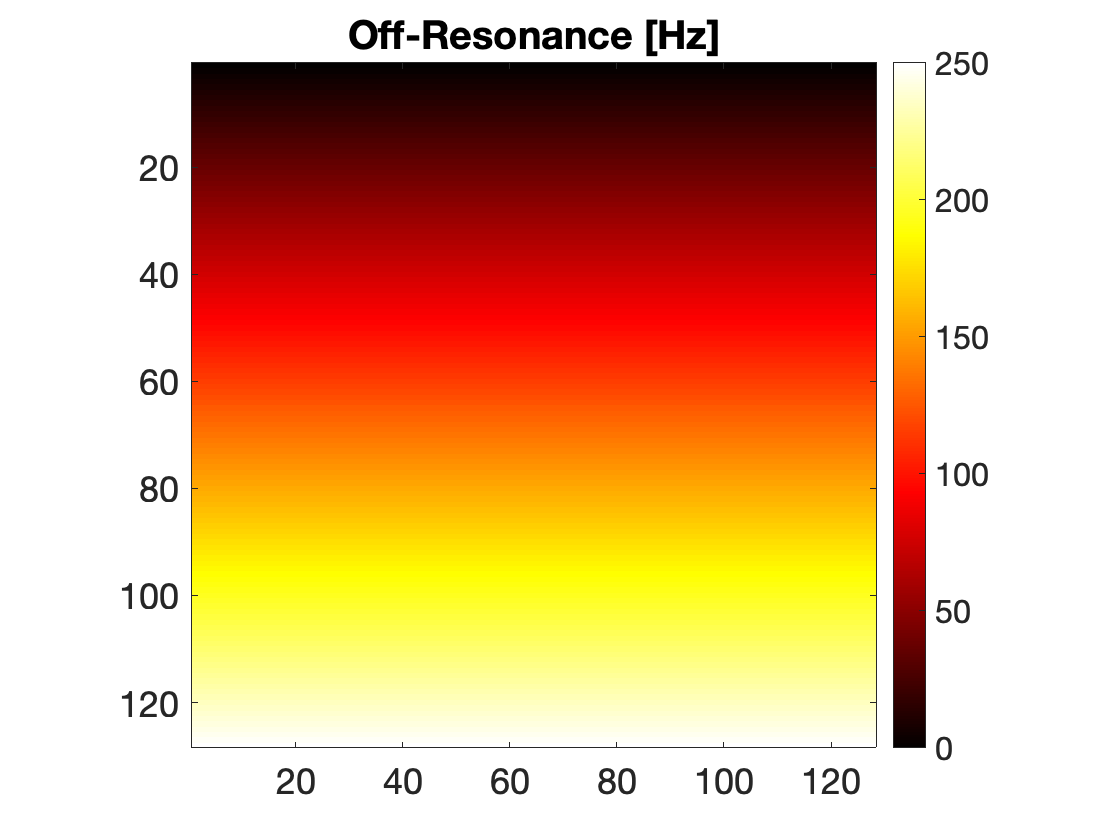

% Linear field (phase encode)
freq_x = linspace( 1 , 1 , acq.Nx );  % Arbitrary off-resonance frequency [Hz]
freq_y = linspace( 0 , 250 , acq.Nx );  % Arbitrary off-resonance frequency [Hz]
freq_scl = freq_y' * freq_x;    % Arbitrary off-resonance frequency across the FOV

% Linear field (frequency encode)
% freq_x = linspace( 0 , 250 , acq.Nx );  % Arbitrary off-resonance frequency [Hz]
% freq_y = linspace( 1 , 1 , acq.Nx );  % Arbitrary off-resonance frequency [Hz]
% freq_scl = freq_y' * freq_x;    % Arbitrary off-resonance frequency across the FOV

% Bi-Quadratic field  
% freq_x = linspace( 0 , 5 , acq.Nx ) .^ 2;  % Arbitrary off-resonance frequency [Hz]
% freq_y = linspace( 0 , 5 , acq.Nx ) .^ 2;  % Arbitrary off-resonance frequency [Hz]
% freq_scl = freq_y' * freq_x;    % Arbitrary off-resonance frequency across the FOV

figure; imagesc(freq_scl); colormap(hot); axis equal tight; colorbar; title('Off-Resonance [Hz]');

## Create a time series of phantoms, add off-resonance, add noise.

P_off = repmat( P , [1 1 acq.Nx] );
for n=1:acq.Nx
  phs_off = exp( -1i * 2 * pi * freq_scl * acp.ESP * n );  % Phase from off-resonance per echo
  P_off( : , : , n ) = P_off( : , : , n ) .* phs_off;  % Object accumulates phase during EPI duration
end

P_off = P_off + ( randn( size(P_off) ) + 1i * randn( size(P_off) ) ) / 25; % Add some complex noise

disp('Maps of the off-resonance [rad] accumulation.')

Maps of the off-resonance [rad] accumulation.


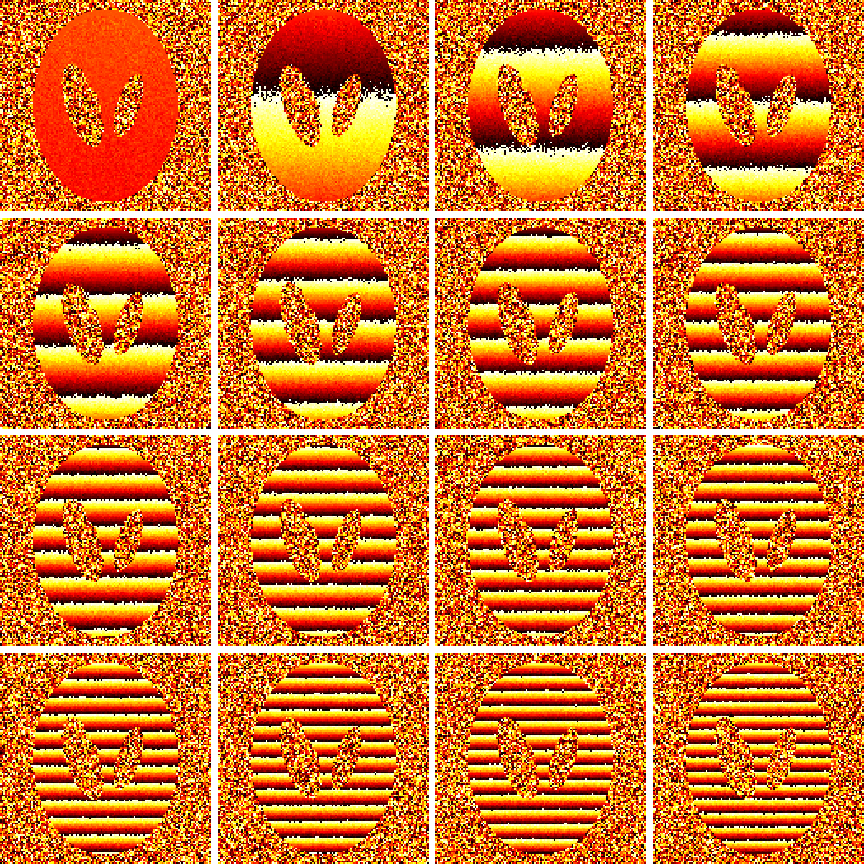

figure; imagescn( angle( P_off( : , : , 1 : 8 : end) ) ); colormap(hot);

## Add noise and eastimate the k-space

kspc_dist = zeros(size(P_off));

for n=1:acq.Nx
  kspc_dist(:,:,n)=fftshift(fft2(P_off(:,:,n))); % Define the k-space for each time
end

## Simulate the TOP-DOWN EPI trajectory

% Grab one echo per ky-line during off-resonance phase accumulation
for n = 1 : acq.Nx
  kspc_epi_dist( n , : ) = kspc_dist( n , : , n ); % Fill the nth-row with the nth-row from the nth-phase
end

IM_epi_dist = ifft2( fftshift( kspc_epi_dist ) ); % Image of distorted object

## Figure of TOP-DOWN EPI distortion

disp('Figure of TOP-DOWN EPI distortion')

Figure of TOP-DOWN EPI distortion


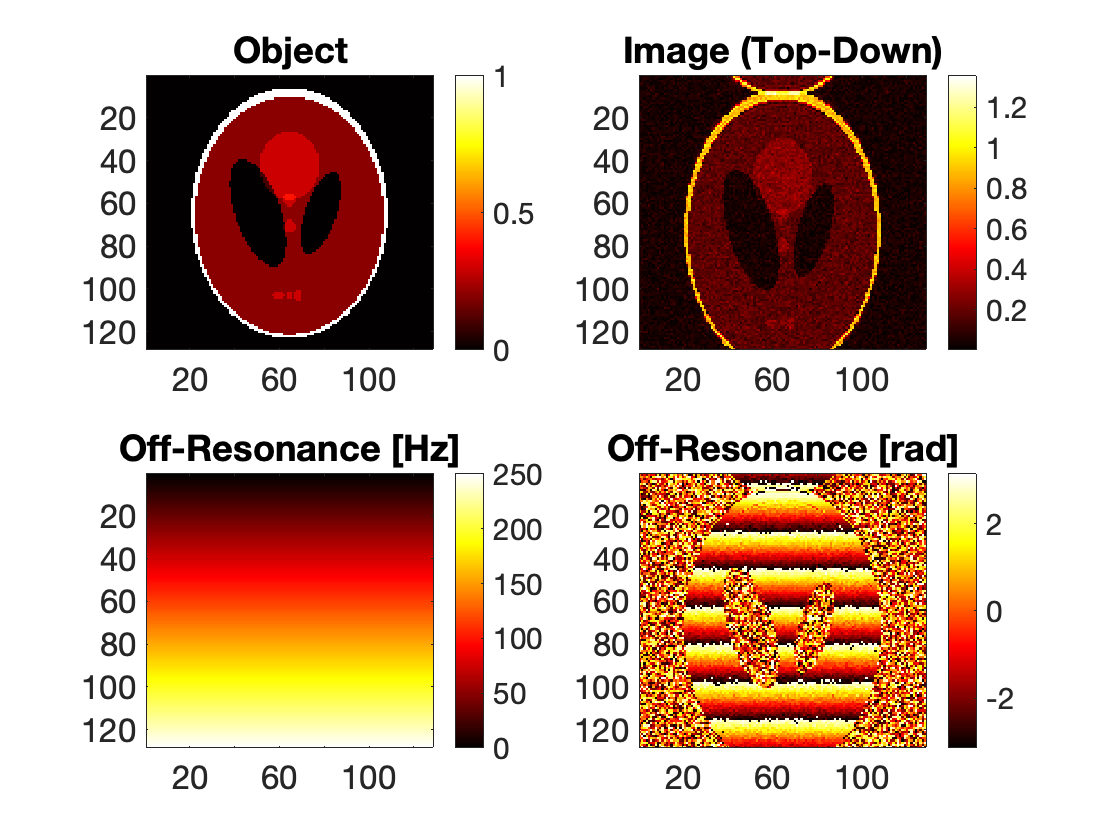

figure; hold on; colormap(hot);
  subplot(2,2,1); imagesc(abs(P)); title('Object'); colorbar;
  subplot(2,2,2); imagesc(abs(IM_epi_dist)); title('Image (Top-Down)'); colorbar;
  subplot(2,2,3); imagesc(freq_scl); title('Off-Resonance [Hz]'); colorbar;
  subplot(2,2,4); imagesc(angle(IM_epi_dist)); title('Off-Resonance [rad]'); colorbar;

## Simulate the BOTTOM-UP EPI trajectory

% Grab one echo per ky-line during off-resonance phase accumulation
for n = 1 : acq.Nx
  kspc_epi_dist( acq.Nx - ( n - 1 ) , : ) = kspc_dist( acq.Nx - ( n - 1 ) , : , n ); % Fill the bottom ky-line (acq.Nx-(n-1)) with the first echo (n)
end

IM_epi_dist2 = ifft2( fftshift ( kspc_epi_dist ) ); % Image of distorted object

## Figure of BOTTOM-UP EPI distortion

disp('Figure of BOTTOM-UP EPI distortion')

Figure of BOTTOM-UP EPI distortion


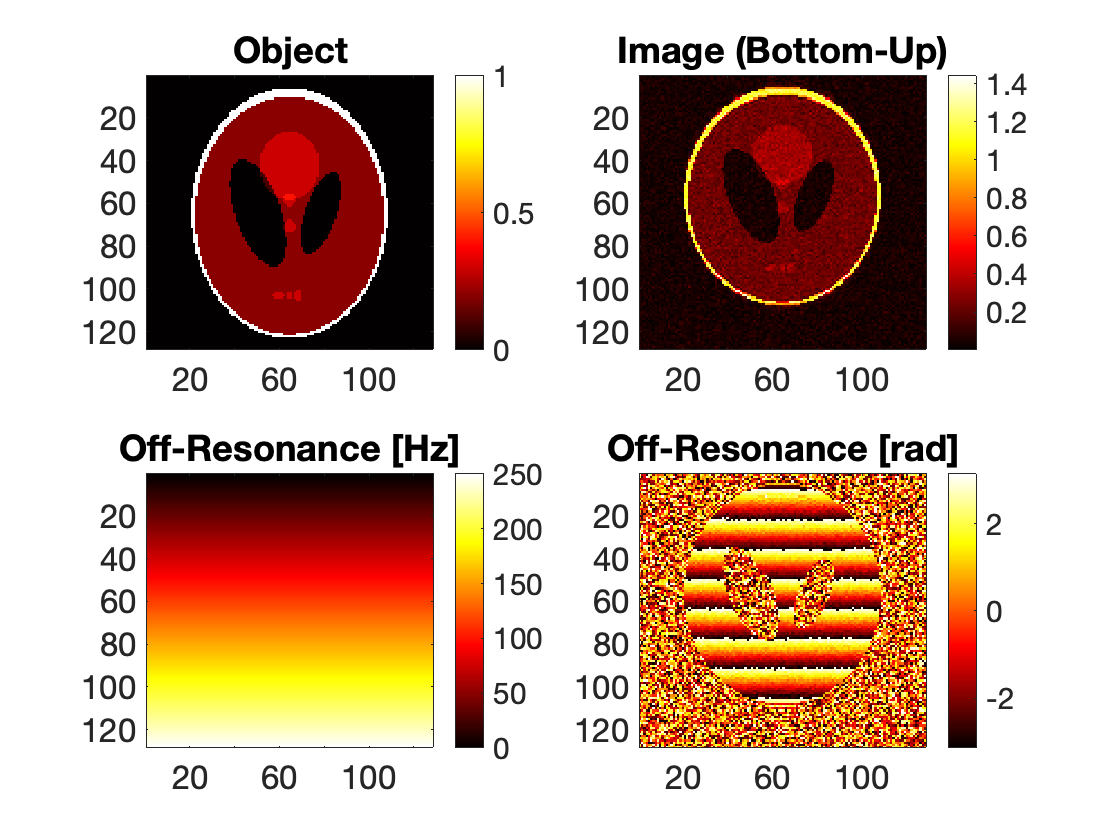

figure; hold on; colormap(hot);
  subplot(2,2,1); imagesc(abs(P)); title('Object'); colorbar;
  subplot(2,2,2); imagesc(abs(IM_epi_dist2)); title('Image (Bottom-Up)'); colorbar;
  subplot(2,2,3); imagesc(freq_scl); title('Off-Resonance [Hz]'); colorbar;
  subplot(2,2,4); imagesc(angle(IM_epi_dist2)); title('Off-Resonance [rad]'); colorbar;